## **Data Analysis**

#### [**Hiroyuki Chihara**](https://fiomfd.github.io/)** (University of the Ryukyus, Okinawa Island, Japan)**

- Public data and visualization

- Central limit theorem

### **1. Public data and visualization**

Let $\vec{x}=[x[1],\dots,x[N]]^T \in \mathbb{R}^N$ be an $N$-dimensional real column vector. This can describes data such as $x[i]$ means the highest temperature of the $i$-th day for $i=1,\dots,N$. One can exploit some information such as the average $m$ and the variance $\sigma^2$: 


$$m:=\frac{1}{N}\sum_{i=1}^Nx[i],
\quad
\sigma^2:=\frac{1}{N}\sum_{i=1}^N(x[i]-m)^2.$$


In what follows MATLAB downloads open data, and visualizes information taking averages, maximums and minimums. More concretely MATLAB downloads 

- the daily maximum tenperature

- the daily minimum tenpereture

- the daily mean tenperature 

of 1884-present at the Hong Kong Observatory. The starting dates of  the theree data are not same, and so we make use of data of 140 years of 1885-2024. The Hong Kong Observatory dataset has no daily temperature records from 1 Jan 1940 to 31 Dec 1946, due to the disruption of WWII and the Japanese occupation. This 7-year gap means that analyses requiring continuous daily data over multiple years will be affected if these years are included. To ensure consistency, we restrict the analysis period to 1 Jan 1947 – 31 Dec 2024.

close;
websave('HK_Maximun_Temperature.csv','https://data.weather.gov.hk/weatherAPI/opendata/opendata.php?dataType=CLMMAXT&rformat=csv&station=HKO');
Amax=readtable('HK_Maximun_Temperature.csv','VariableNamingRule', 'preserve');
Amax=Amax(367:48944,1:4);
Amax.Properties.VariableNames = {'Year', 'Month', 'Day', 'Max'};
websave('HK_Minimun_Temperature.csv','https://data.weather.gov.hk/weatherAPI/opendata/opendata.php?dataType=CLMMINT&rformat=csv&station=HKO');
Amin=readtable('HK_Minimun_Temperature.csv','VariableNamingRule', 'preserve');
Amin=Amin(367:48944,4);
Amin.Properties.VariableNames = {'Min'};
websave('HK_Mean_Temperature.csv','https://data.weather.gov.hk/weatherAPI/opendata/opendata.php?dataType=CLMTEMP&rformat=csv&station=HKO');
Amean=readtable('HK_Mean_Temperature.csv','VariableNamingRule', 'preserve');
Amean=Amean(307:48884,4);
Amean.Properties.VariableNames = {'Mean'};
A=[Amax Amean Amin]

A = 48578×6 table
    Year    Month    Day    Max     Mean    Min 
    ____    _____    ___    ____    ____    ____

    1885      1       1     17.8    15.3    13.9
    1885      1       2     20.5    16.7    14.2
    1885      1       3     16.6    15.4    14.8
    1885      1       4     18.6    16.1    14.6
    1885      1       5     20.8    17.5    15.1
    1885      1       6     21.1    18.3    16.8
    1885      1       7     19.9    17.9    15.4
    1885      1       8     17.3    15.6    14.2
    1885      1       9     16.9    15.7    14.7
    1885      1      10     18.1    16.1    15.1
    1885      1      11     19.9    17.2    15.3
    1885      1      12     17.9      16    14.9
    1885      1      13     17.1    14.4    11.9
    1885      1      14     17.1    13.6  

MATLAB computes the annual maximum, average, and minmum temperatures, and shows the line graphs. One can see that the annual maximum, average and minimum temperatures have been increasing year and year. 

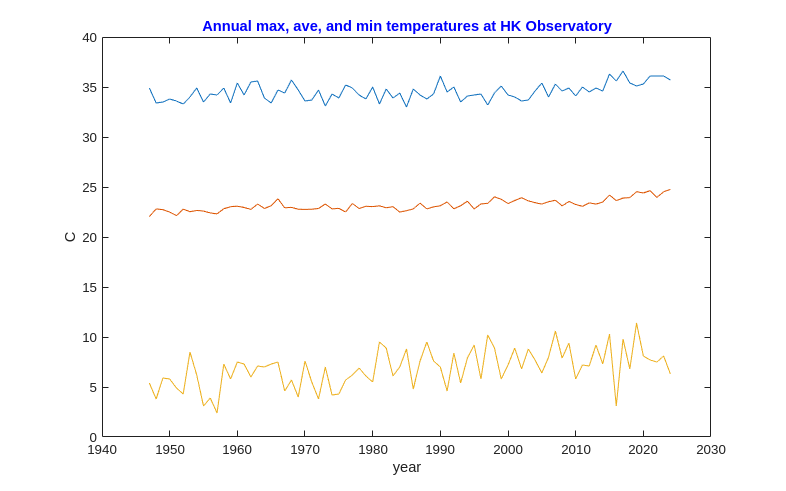

A1=A(20089:48578,:);
AA = A1{:,["Max","Mean","Min"]};
B=zeros(78,3);
X=zeros(78,1);
L=0;
for i=1:78
    if (mod(1946+i,4)==0 && mod(1946+i,100)~=0) || mod(1946+i,400)==0
       B(i,1)=max(AA(L+1:L+366,1));
       B(i,2)=mean(AA(L+1:L+366,2));
       B(i,3)=min(AA(L+1:L+366,3));
       L=L+366;
       X(i,1)=1946+i;
    else
       B(i,1)=max(AA(L+1:L+365,1));
       B(i,2)=mean(AA(L+1:L+365,2));
       B(i,3)=min(AA(L+1:L+365,3));
       L=L+365;
       X(i,1)=1946+i;
    end
end

figure('Position',[100 100 800 500])
plot(X,B(:,1),X,B(:,2),X,B(:,3))
title('Annual max, ave, and min temperatures at HK Observatory','Color','blue')
xlabel('year')
ylabel('C')
xlim([1940 2030])

Moreover, MATLAB computes the monthy maximum, average, and minmum temperatures, and shows the line graphs in each year. Choose the year using the slider. 

Bmax=zeros(78,12);
Bmean=zeros(78,12);
Bmin=zeros(78,12);
Y=zeros(1,12);
M=0;

for j=1:12
    Y(1,j)=j;
end

for i=1:78
    if (mod(1946+i,4)==0 && mod(1946+i,100)~=0) || mod(1946+i,400)==0
       % leap year
       % January 
       Bmax(i,1)=max(AA(M+1:M+31,1));
       Bmean(i,1)=mean(AA(M+1:M+31,2));
       Bmin(i,1)=min(AA(M+1:M+31,3));
       % February
       Bmax(i,2)=max(AA(M+32:M+60,1));
       Bmean(i,2)=mean(AA(M+32:M+60,2));
       Bmin(i,2)=min(AA(M+32:M+60,3));
       % March
       Bmax(i,3)=max(AA(M+61:M+91,1));
       Bmean(i,3)=mean(AA(M+61:M+91,2));
       Bmin(i,3)=min(AA(M+61:M+91,3));
       % April
       Bmax(i,4)=max(AA(M+92:M+121,1));
       Bmean(i,4)=mean(AA(M+92:M+121,2));
       Bmin(i,4)=min(AA(M+92:M+121,3));
       % May
       Bmax(i,5)=max(AA(M+122:M+152,1));
       Bmean(i,5)=mean(AA(M+122:M+152,2));
       Bmin(i,5)=min(AA(M+122:M+152,3));
       % June
       Bmax(i,6)=max(AA(M+153:M+182,1));
       Bmean(i,6)=mean(AA(M+153:M+182,2));
       Bmin(i,6)=min(AA(M+153:M+182,3));
       % July
       Bmax(i,7)=max(AA(M+183:M+213,1));
       Bmean(i,7)=mean(AA(M+183:M+213,2));
       Bmin(i,7)=min(AA(M+183:M+213,3));
       % August
       Bmax(i,8)=max(AA(M+214:M+244,1));
       Bmean(i,8)=mean(AA(M+214:M+244,2));
       Bmin(i,8)=min(AA(M+214:M+244,3));
       % September
       Bmax(i,9)=max(AA(M+245:M+274,1));
       Bmean(i,9)=mean(AA(M+245:M+274,2));
       Bmin(i,9)=min(AA(M+245:M+274,3));
       % October
       Bmax(i,10)=max(AA(M+275:M+305,1));
       Bmean(i,10)=mean(AA(M+275:M+305,2));
       Bmin(i,10)=min(AA(M+275:M+305,3));
       % November
       Bmax(i,11)=max(AA(M+306:M+335,1));
       Bmean(i,11)=mean(AA(M+306:M+335,2));
       Bmin(i,11)=min(AA(M+306:M+335,3));
       % December
       Bmax(i,12)=max(AA(M+336:M+366,1));
       Bmean(i,12)=mean(AA(M+336:M+366,2));
       Bmin(i,12)=min(AA(M+336:M+366,3));
       M=M+366;
    else
       Bmax(i,1)=max(AA(M+1:M+31,1));
       Bmean(i,1)=mean(AA(M+1:M+31,2));
       Bmin(i,1)=min(AA(M+1:M+31,3));
       Bmax(i,2)=max(AA(M+32:M+59,1));
       Bmean(i,2)=mean(AA(M+32:M+59,2));
       Bmin(i,2)=min(AA(M+32:M+59,3));
       Bmax(i,3)=max(AA(M+60:M+90,1));
       Bmean(i,3)=mean(AA(M+60:M+90,2));
       Bmin(i,3)=min(AA(M+60:M+90,3));
       Bmax(i,4)=max(AA(M+91:M+120,1));
       Bmean(i,4)=mean(AA(M+91:M+120,2));
       Bmin(i,4)=min(AA(M+91:M+120,3));
       Bmax(i,5)=max(AA(M+121:M+151,1));
       Bmean(i,5)=mean(AA(M+121:M+151,2));
       Bmin(i,5)=min(AA(M+121:M+151,3));
       Bmax(i,6)=max(AA(M+152:M+181,1));
       Bmean(i,6)=mean(AA(M+152:M+181,2));
       Bmin(i,6)=min(AA(M+152:M+181,3));
       Bmax(i,7)=max(AA(M+182:M+212,1));
       Bmean(i,7)=mean(AA(M+182:M+212,2));
       Bmin(i,7)=min(AA(M+182:M+212,3));
       Bmax(i,8)=max(AA(M+213:M+243,1));
       Bmean(i,8)=mean(AA(M+213:M+243,2));
       Bmin(i,8)=min(AA(M+213:M+243,3));
       Bmax(i,9)=max(AA(M+244:M+273,1));
       Bmean(i,9)=mean(AA(M+244:M+273,2));
       Bmin(i,9)=min(AA(M+244:M+273,3));
       Bmax(i,10)=max(AA(M+274:M+304,1));
       Bmean(i,10)=mean(AA(M+274:M+304,2));
       Bmin(i,10)=min(AA(M+274:M+304,3));
       Bmax(i,11)=max(AA(M+305:M+334,1));
       Bmean(i,11)=mean(AA(M+305:M+334,2));
       Bmin(i,11)=min(AA(M+305:M+334,3));
       Bmax(i,12)=max(AA(M+335:M+365,1));
       Bmean(i,12)=mean(AA(M+335:M+365,2));
       Bmin(i,12)=min(AA(M+335:M+365,3));
       M=M+365;
    end
end

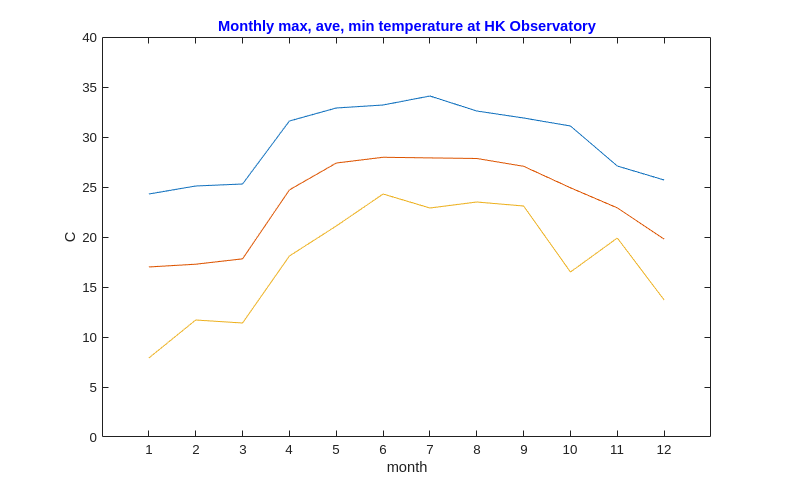

year =1994;
figure('Position',[100 100 800 500])
plot(Y,Bmax(year-1946,:),Y,Bmean(year-1946,:),Y,Bmin(year-1946,:))
title('Monthly max, ave, min temperature at HK Observatory','Color','blue')
xlabel('month')
ylabel('C')
xlim([0 13])
ylim([0 40])
xticks([1 2 3 4 5 6 7 8 9 10 11 12])

### 2. Central limit theorem for the binomial distribution $B(n,p)$

Let $n$ be a positive integer, and let $p$ be a constant satisfying $0 < p < 1$. Denote by $B(n,p)$ the the binomial distribution of $n$ iid experiments $X_1,\dots,X_n$ with probability $p$, that is, a discrete probability distribution on $\{0,1,\dots,n\}$ such that 


$$\text{P}(S_n=k)=\frac{n!}{k!(n-k)!}p^k(1-p)^{n-k}, 
\quad
k=0,1,\dots,n,$$


where $S_n:=X_1+\cdots+X_n$. It is well-known that for any $a,b\in\mathbb{R}$ with $a<b$, 


$$\text{P}
\left(
a \leq \frac{S_n-pn}{\sqrt{np(1-p)}} \leq b
\right)
\rightarrow
\frac{1}{\sqrt{2\pi}}
\int_a^be^{-x^2/2}dx
\quad
(n \rightarrow \infty),$$


which is a typical example of the central limit theorem. We now observe this phenomenon for $p=0.1,\dots,0.9$. 

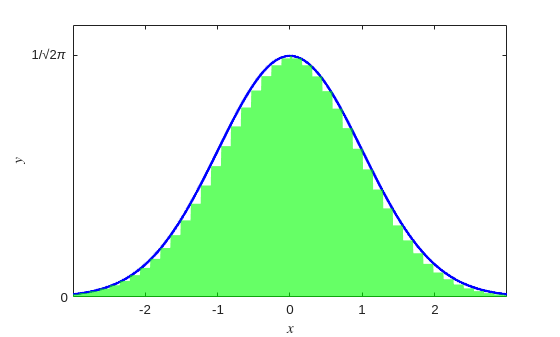

close;
n = 244;
p = 0.7;

x1 = linspace(-3, 3, 1201);
f1 = exp(-x1.^2/2) / sqrt(2*pi);

sigma = sqrt(n*p*(1-p));
off   = max(100, n);

z2 = zeros(1, n + 2*off);
l = 0:n;
logpmf = gammaln(n+1) - gammaln(l+1) - gammaln(n-l+1) ...
         + l.*log(p) + (n-l).*log1p(-p) + log(sigma);
z2(off + 1 + l) = exp(logpmf);

z1 = zeros(1, length(x1));
c1 = (length(x1) - 1) / 2;
idx = 0:(c1-1);
Lr = floor(n*p + (idx/200).*sigma);
Ll = floor(n*p - (idx/200).*sigma);

z1(c1 + (1:c1))       = z2(off + 2 + Lr);
z1(c1 + 1 - (1:c1))   = z2(off + 1 + Ll);

assert(~any(isnan(z2)) && ~any(isnan(z1)));

figure;
plot(x1, exp(-x1.^2/2)/sqrt(2*pi), 'b-', 'LineWidth', 2); 
hold on;
area(x1, z1, 'FaceColor','green','FaceAlpha', 0.6, 'EdgeColor','none');
hold off;
ylim([0, 0.45]); 
grid off;
set(gca,'XTick',[-2 -1 0 1 2]);
set(gca,'YTick',[0 1/sqrt(2*pi)],'YTickLabel',{'0','1/\surd{2\pi}'});
xlabel('$x$','Interpreter','latex'); ylabel('$y$','Interpreter','latex');